A = [0 0 1 0; 0 0 0 1; 0 1 0 0; 1 0 0 0]

A =      0     0     1     0
     0     0     0     1
     0     1     0     0
     1     0     0     0


x0 = [1 1 -1 -1]'

x0 =      1
     1
    -1
    -1


sim('problem2model')

ans =   Simulink.SimulationOutput:

                   tout: [51x1 double] 
                      x: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


[v,d] = eig(A)

v =   -0.5000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.5000i  -0.5000 + 0.0000i
  -0.5000 + 0.0000i  -0.0000 + 0.5000i  -0.0000 - 0.5000i  -0.5000 + 0.0000i
   0.5000 + 0.0000i   0.5000 + 0.0000i   0.5000 - 0.0000i  -0.5000 + 0.0000i
   0.5000 + 0.0000i  -0.5000 + 0.0000i  -0.5000 + 0.0000i  -0.5000 + 0.0000i


d =   -1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i


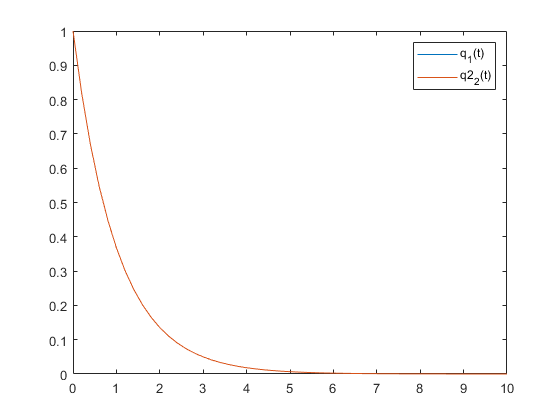

t = out.x.Time;
q1 = out.x.Data(:,1);
q2 = out.x.Data(:,2);
plot(t,q1)
hold on
plot(t,q2)
legend('q_{1}(t)','q2_{2}(t)')
hold off

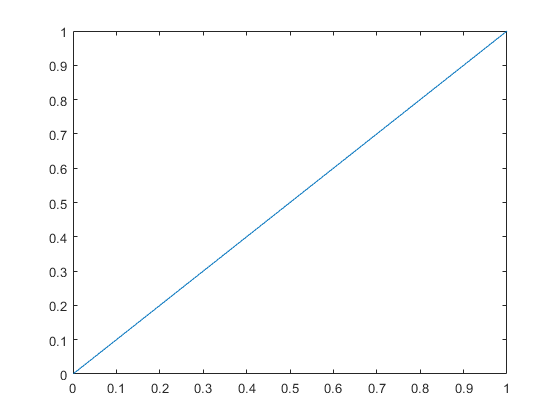

plot(q1,q2)


B = [v(:,1) v(:,2) v(:,3) v(:,4) x0]

B =   -0.5000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.5000i  -0.5000 + 0.0000i   1.0000 + 0.0000i
  -0.5000 + 0.0000i  -0.0000 + 0.5000i  -0.0000 - 0.5000i  -0.5000 + 0.0000i   1.0000 + 0.0000i
   0.5000 + 0.0000i   0.5000 + 0.0000i   0.5000 - 0.0000i  -0.5000 + 0.0000i  -1.0000 + 0.0000i
   0.5000 + 0.0000i  -0.5000 + 0.0000i  -0.5000 + 0.0000i  -0.5000 + 0.0000i  -1.0000 + 0.0000i


C = rref(B)

C =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i


C = C(:,end)

C =   -2.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i


xt = C(1)*exp(d(1,1)*t').*v(:,1)...
    + C(2)*exp(d(2,2)*t').*v(:,2)...
    + C(3)*exp(d(3,3)*t').*v(:,3)...
    + C(4)*exp(d(4,4)*t').*v(:,4)

xt =    1.0000 - 0.0000i   0.8187 - 0.0000i   0.6703 - 0.0000i   0.5488 - 0.0000i   0.4493 - 0.0000i   0.3679 - 0.0000i   0.3012 - 0.0000i   0.2466 - 0.0000i   0.2019 - 0.0000i   0.1653 - 0.0000i   0.1353 - 0.0000i   0.1108 - 0.0000i   0.0907 - 0.0000i   0.0743 - 0.0000i   0.0608 - 0.0000i   0.0498 - 0.0000i   0.0408 + 0.0000i   0.0334 + 0.0000i   0.0273 + 0.0000i   0.0224 + 0.0000i   0.0183 + 0.0000i   0.0150 + 0.0000i   0.0123 + 0.0000i   0.0101 + 0.0000i   0.0082 + 0.0000i   0.0067 - 0.0000i   0.0055 + 0.0000i   0.0045 + 0.0000i   0.0037 + 0.0000i   0.0030 - 0.0000i   0.0025 - 0.0000i   0.0020 - 0.0000i   0.0017 - 0.0000i   0.0014 - 0.0000i   0.0011 - 0.0000i   0.0009 - 0.0000i   0.0007 - 0.0000i   0.0006 - 0.0000i   0.0005 - 0.0000i   0.0004 - 0.0000i   0.0003 - 0.0000i   0.0003 - 0.0000i   0.0002 - 0.0000i   0.0002 - 0.0000i   0.0002 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 + 0.0000i
   1.0000 - 0.0000i   0.8187 + 0.0000i   0.6

plot(t,xt(1,:))

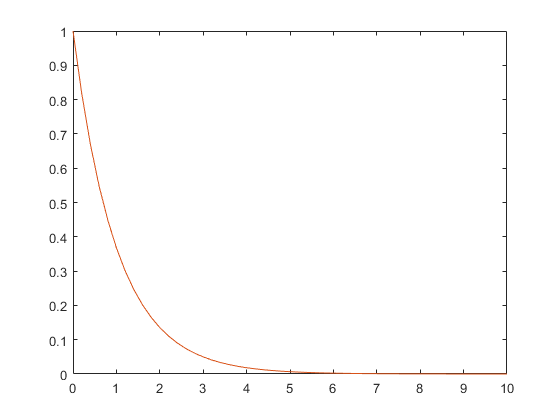

hold on
plot(t,xt(2,:))